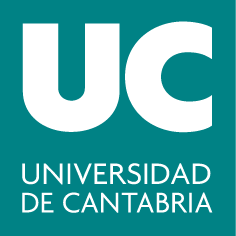

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 2: Integral Doble. Teorema del valor medio**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Dibujar con Matlab regiones planas limitadas por curvas dadas por una ecuación en coordenadas cartesianas.

- Aplicar las propiedades de las integrales dobles sobre láminas (Teorema del Valor Medio).

### Resumen teórico

#### Integrales iteradas sobre dominios regulares

Un conjunto $D$ del plano es y-simple si se puede escribir como $D=\lbrace (x,y) / a \leq x \leq b, \phi_{1}(x) \leq y \leq \phi_{2}(x)\rbrace$. Si la función $f(x,y)$ es integrable en $D$, entonces:


$$\displaystyle \int\int_{D}f(x,y) dA=\int_{a}^b\int_{\phi_{1}(x)}^{\phi_{2}(x)}f(x,y)dydx$$


Un conjunto $D$ del plano es x-simple si se puede escribir como $D=\lbrace (x,y) / c \leq y \leq d, \psi_{1}(y) \leq x \leq \psi_{2}(y)\rbrace$. Si la función $f(x,y)$ es integrable en $D$, entonces:


$$\displaystyle \int\int_{D}f(x,y) dA=\int_{c}^d\int_{\psi_{1}(y)}^{\psi_{2}(y)}f(x,y)dxdy$$


#### Algunas aplicaciones

**Teorema del valor medio**: Si $f(x,y)$ es continua en un dominio, en algun punto del dominio se alcanzará el valor medio de la función.


$$\text{Área(D)}=\int\int_{D}dA$$
                        
$$\text{Valor medio}=\frac{\int\int_{D}f(x,y)dA}{Área(D)}$$


### Comandos útiles

#### Comandos para trabajar con vectores

- `a:h:b `Genera un vector fila de primer elemento `a` y los demás elementos aumentan de `h` en `h` hasta no superar `b`.

- `linspace(a, b, n)`:  Generar un vector fila de `n` (100 por defecto) componentes equidistnates cuyo primer elemento es `a` y el último `b.`

#### Comandos para dibujar en el plano

- `plot(x, y, 's')`: Realiza un gráfico con los puntos de coordenadas cartesianas definidas por los vectores `x` e `y`, con el estilo indicado en `'s'`.

- `fill(x,y,``'c'``): `Dibuja polígonos en el plano, cuyos vértices tienen las coordenadas recogidas en los vectores `x,y` , y los rellena del color especificado en  `'c'`. Si es necesario, cierra el polígono conectando el último vértice con el primero.

- `grid on / grid off:` Para poner o quitar la cuadrícula del fondo de una figura.

- `hold on:` Permite seguir dibujando en la misma figura hasta que aparezca `hold off`.

- `axis equal: `Para igualar la escala de todos los ejes coordenados para que la proporción sea 1:1.

- `view(az, el)`: Controla el punto de vista de una representación con diferentes parámetros. Sitúa el punto de vista de la figura en el indicado por los ángulos az (azimutal) y el (ángulo de elevación sobre el plano z=0), expresados en grados. `view(2)` ó `view(0,90)` sirven para recuperar la vista en 2-D.

- `xlabel, ylabel: `Pone una etiqueta en los ejes cartesianos de la gráfica.

- `shading interp: `Varía el color de cada línea o cara de la superficie que se dibuja interpolando el mapa de colores, consiguiendo un efecto más suave en la variación del color. Trabaja con diferentes comandos: `surf, mesh`, etc.

#### Comandos para calcular de forma exacta la integral de una función sobre un intervalo cerrado

- `syms x`: Crea la variable simbólica `x`.

- `int(int(f(x,y), y, phi1(x), phi2(x)), x, a, b)`: para calcular la integral doble:


$$\int_{a}^{b}\int_{\phi_{1}(x)}^{\phi_{2}(x)} f(x,y) dy dx$$


- `double(x): `Convierte a decimal con doble precisión los valores recogidos en x, que puede ser una matriz o vector de valores. 

###  Ejercicio resuelto

- **Aplicación del Teorema del Valor Medio sobre una lámina**

Sea $A$ la región y-simple del plano definida como: $A=\lbrace (x,y)\in \mathbb{R}^2 / 0 \leq x \leq 1, x \leq y \leq \sqrt{x}\rbrace$. Se pide:

a) Representa con Matlab la región $A$ con color amarillo. 

b) Calcula el área de $A$  con Matlab.

c) Defínela cambiando el orden (escríbela como x-simple) y calcula de nuevo el área.

d) Supondremos que esta región es una lámina (sin grosor) de un material de densidad de masa proporcional en cada punto a la distancia del punto al eje $y=0$, tomando la constante de proporcionalidad $k=1$. Calcula la densidad media de la lámina. Encuentra los puntos de la placa donde se alcanza esta densidad media. 		

e) Destaca sobre la lámina de la figura anterior los puntos que donde se alcanza la densidad media, éstos de color verde. 	

f) Representa ahora con Matlab la misma figura, pero coloreando la placa según el valor de la densidad de masa. Para ello, puedes usar el comando `surf`, tomando $z=0$.

a) Representa con Matlab la región $A$ con color amarillo. 

%Dibuja la región plana ocupada por la placa
%Asigna a x 100 valores igualmente espaciados entre 0 y 1
x=linspace(0,1);
y=sqrt(x);
figure(1)
fill([x,0],[y,0],'y') % Añade vértice [0,0] para cerrar el polígono (aquí es opcional)
axis equal
hold on

b) Calcula el área de $A$  con Matlab.

syms u v
area=int(int(1,v,u,sqrt(u)),u,0,1)

c) Defínela cambiando el orden (escríbela como x-simple) y calcula de nuevo el área.

Región x-simple: $A=\lbrace (x,y) \in \mathbb{R}^2 / 0 \leq y \leq 1, y^2 \leq x \leq y\rbrace$

area2=int(int(1,u,v^2,v),v,0,1)

d) Supondremos que esta región es una lámina (sin grosor) de un material de densidad de masa proporcional en cada punto a la distancia del punto al eje $y=0$, tomando la constante de proporcionalidad $k=1$. Calcula la densidad media de la lámina. Encuentra los puntos de la placa donde se alcanza esta densidad media. 	

Si la densidad es proporcional a la distancia al eje OX ($$y=0$$) con constante de proporcionalidad $k=1$, será directamente la coordenada $y$ de cada punto:


$$\delta(x,y)= y$$


densidad=v;
densidad_media=int(int(densidad,v, u,sqrt(u)),u,0,1)/area

El lugar geométrico de los puntos con densidad media sobre $A$ deben cumplir:  $\delta_{m}(x,y)= y_{m}=\frac{1}{2}$    

Hallamos los puntos de corte de esa recta con $y=\sqrt{x$ , $y=x$ para encontrar el segmento de puntos con esa densidad media:

- Punto de corte de $y=\frac{1}{2}$, $y=\sqrt{x}$  $\Rightarrow x=y^{2}=\frac{1}{4}$        

- Punto de corte de  $y=\frac{1}{2}$, $y=x$   $\Rightarrow x= y=\frac{1}{2}$        

Por lo tanto, el lugar geométrico en que se alcanza la densidad media está formado por el segmento: 


$$\lbrace (x,y) / y=\frac{1}{2}, \frac{1}{4} \leq x \leq \frac{1}{2} \rbrace$$


e) Destaca sobre la lámina de la figura anterior  los puntos que donde se alcanza la densidad media, éstos de color verde. 	

xm=1/4:.01:1/2; 
ym=1/2*ones(size(xm));
plot(xm,ym,'g','LineWidth',2) % asigna al grosor de la línea 2 unidades
grid on
axis equal
hold off

f) Representa ahora con Matlab la misma figura, pero coloreando la placa según el valor de la densidad de masa. Para ello, puedes usar el comando `surf`, tomando $z=0$.

x=linspace(0,1); y=x; %crear vectores para la representación con surf del rectángulo
[X,Y]=meshgrid(x,y);
Z=zeros(size(X));
%Dibuja en el plano z=0 el mapa de color de la función densidad
figure(2)
h1=surf(X,Y,Z,Y); % el cuarto argumento indica el color (función densidad de masa)
set(h1,'FaceAlpha',0.5)
shading interp
hold on
%Dibuja sobre la misma figura el contorno de la lámina en negro
y2=sqrt(x); %ordenadas del trozo de parábola
plot(x,y,'k', x, y2,'k') % pinta en negro el contorno de la lámina
%Dibuja los puntos de la placa donde se alcanza la temperatura media
plot(xm,ym,'r','LineWidth',2)
grid on
axis equal
colorbar
view(2) % equivalente a view(0,90)
hold off